# Example: COVID-2019 data for South korea  (22-Jan-2020 - )

I am taking some data, collected into DATA.mat from John Hopkins university [1]

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
% Download the data from ref [1] and read them with the function getDataCOVID
[tableConfirmed,tableDeaths,tableRecovered,time] = getDataCOVID();
% time = time(1:end-1);
fprintf(['Most recent update: ',datestr(time(end)),'\n'])

Most recent update: 03-Apr-2020




Location = 'Korea';


try
    indR = find(contains(tableRecovered.CountryRegion,Location)==1);
    indC = find(contains(tableConfirmed.CountryRegion,Location)==1);
    indD = find(contains(tableDeaths.CountryRegion,Location)==1);
catch exception
    searchLoc = strfind(tableRecovered.CountryRegion,Location);
    indR = find([searchLoc{:}]==1);
    
    searchLoc = strfind(tableConfirmed.CountryRegion,Location);
    indC = find([searchLoc{:}]==1);
    
    searchLoc = strfind(tableConfirmed.CountryRegion,Location);
    indD = find([searchLoc{:}]==1);
    
    
end

tableRecovered(indR,1:2)

ans = 1×2 table
    ProvinceState    CountryRegion 
    _____________    ______________

      <missing>      "Korea, South"


indR = indR(1)

indR = 139



Recovered = table2array(tableRecovered(indR,5:end));
Deaths = table2array(tableDeaths(indD,5:end));
Confirmed = table2array(tableConfirmed(indC,5:end));
% If the number of confirmed Confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases
minNum= round(0.025*max(Confirmed));
Recovered(Confirmed<=minNum)=[];
Deaths(Confirmed<=minNum)=[];
time(Confirmed<=minNum)= [];
Confirmed(Confirmed<=minNum)=[];

Npop= 60e6; % population

## Fitting of the generalized SEIR model to the real data

% Definition of the first estimates for the parameters
alpha_guess = 0.06; % protection rate
beta_guess = 1.0; % Infection rate
LT_guess = 5; % latent time in days
QT_guess = 21; % quarantine time in days
lambda_guess = [0.1,0.05]; % recovery rate
kappa_guess = [0.1,0.05]; % death rate

guess = [alpha_guess,...
    beta_guess,...
    1/LT_guess,...
    1/QT_guess,...
    lambda_guess,...
    kappa_guess];


% Initial conditions
E0 = Confirmed(1); % Initial number of exposed cases. Unknown but unlikely to be zero.
I0 = Confirmed(1); % Initial number of infectious cases. Unknown but unlikely to be zero.
Q0 = Confirmed(1);
R0 = Recovered(1);
D0 = Deaths(1);

Active = Confirmed-Recovered-Deaths;
Active(Active<0) = 0; % No negative number possible
[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
    fit_SEIQRDP(Active,Recovered,Deaths,Npop,E0,I0,time,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          9      3.2925e+10                      1.65e+12
     1         18     5.52039e+09      0.0433669        2.3e+11      
     2         27      1.1917e+09      0.0543782       3.69e+10      
     3         36      4.1396e+08      0.0892439       8.67e+09      
     4         45     2.57736e+08       0.122917       1.21e+09      
     5         54     1.88796e+08      0.0622419       1.64e+09      
     6         63     1.86491e+08       0.002593       1.63e+09      
     7         72      1.8479e+08     0.00108845       7.16e+08      
     8         81     1.20457e+08      0.0561335       9.69e+09      
     9         90     6.20661e+07        0.35483       3.49e+08      
    10         99     3.88526e+07      0.0303451       6.33e+09      
    11        108     1.90706e+07       0.217834       1.78e+09      
    12        117     1.90706e+0

## Simulate the epidemy outbreak based on the fitted parameters

dt = 0.1; % time step
time1 = datetime(time(1)):dt:datetime(datestr(floor(datenum(now))+datenum(10)));
N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);

## Comparison of the fitted and real data

Active cases = Confirmed-Deaths-Recovered (database) = Quarantined (SEIQRDP model)

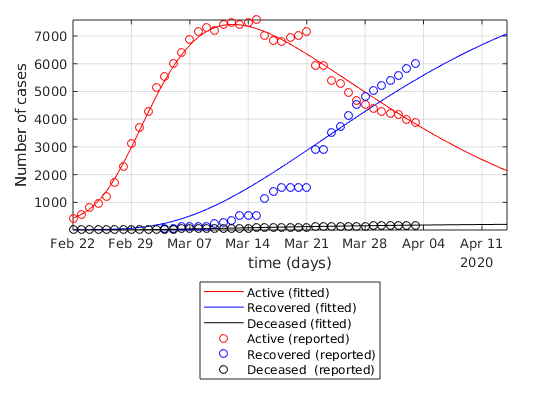

figure
semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Active,'ro',time,Recovered,'bo',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
leg = {'Active (fitted)',...
        'Recovered (fitted)','Deceased (fitted)',...
        'Active (reported)','Recovered (reported)','Deceased  (reported)'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
% ylim([1,8e4])
 set(gca,'yscale','lin')